%quick visualization of layer stat thingy, which was produced by the
%layervalues function.
%e.g. usage 
% s1data_forcognlvlsconj=layervalues('S1','cognlvls','visualization','no');
% allroi = struct('s1', s1data_forpainlvlsconj, 's2', s2data_forpainlvlsconj,'s1_maineff',s1data_formaineffectcolumnselection,'pIns',pInsdata_forpainlvlsconj,'dlpfc',dlpfcdata_forpainlvlsconj,'s1_cognlvl',s1data_forcognlvlsconj);
% save('allroi_withpainlvlcolumnarselection.mat', 'allroi');
% allsubjlayer=dlpfcdata_forpainlvlsconj;

for i = 1:numel(allroi)
    allsubjlayer{i} = allroi(i).s1;
end

topdown_beta=cell(2,1);
bottom_beta=cell(2,1);
topdown_t=cell(2,1);
bottomup_t=cell(2,1);
for roi=1:2
    for subj=1:length(allsubjlayer)
        topdown_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        bottom_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);
%         topdown_beta{roi}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,1);
%         bottom_beta{roi}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,2);


%         topdown_t{roi}(subj,:)=allsubjlayer{subj,1}{1,roi}.T(:,1);
%         bottomup_t{roi}(subj,:)=allsubjlayer{subj,1}{1,roi}.T(:,2);      
    end
end

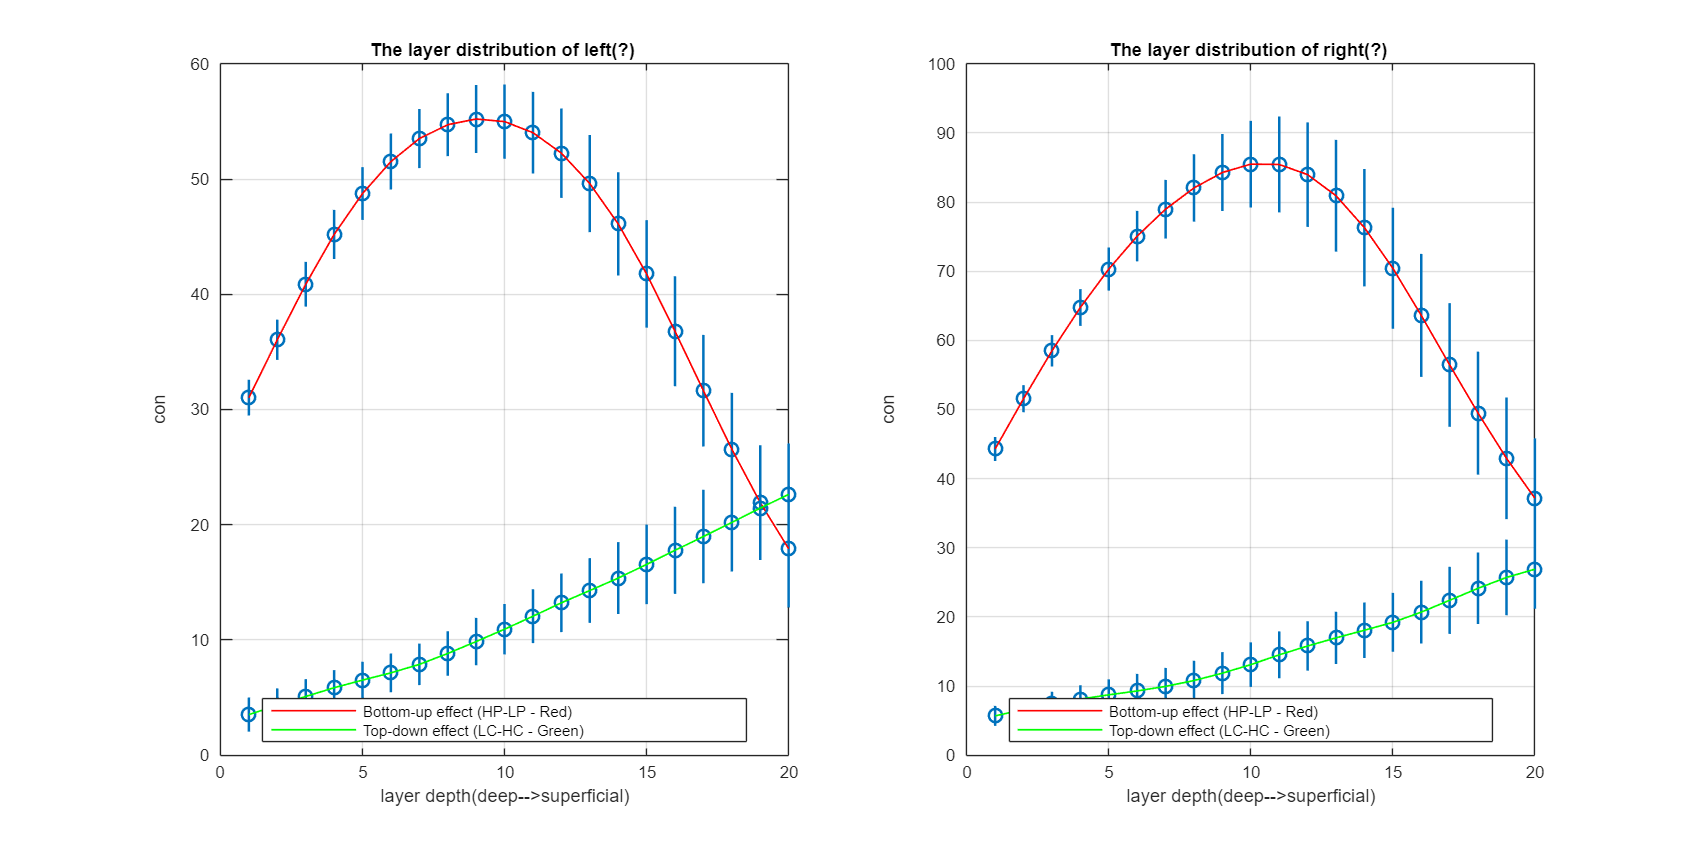

figure('Position',[100, 100, 2400, 1200]);

alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottom_beta{roitype,1}, topdown_beta{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) ';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) ';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end

%save only the main effect contrasts
nproc=2;
nsubj=length(allsubjid);
nside=2;
onecond=array2table([topdown_beta{1};topdown_beta{2}],'VariableNames',strcat("layer",string(1:20)));
onecond.process=repmat("topdown",nsubj*nside,1);
onecond.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottom_beta{1};bottom_beta{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

myergion=[onecond;bu];

myergion.subjid=string(repmat(allsubjid',nproc*nside,1));

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

% writetable(myergion,[ pathtooutput 's1_layervalues_adaptedscript.csv'])

%check the per condition thingies
% 
% 
allsubjlayer=dlpfcpercondition;
topdown_beta=cell(2,1);
bottom_beta=cell(2,1);
topdown_t=cell(2,1);
bottomup_t=cell(2,1);
for roi=1:2
    for subj=1:length(allsubjlayer)
        %     {'pain_high_cogn_high_pain'   }
        %     {'pain_high_cogn_low_pain'    }
        %     {'pain_low_cogn_high_pain'    }
        %     {'pain_low_cogn_low_pain'     }
        HCHP{roi,1}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,1);
        HCLP{roi,1}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,2);
        LCHP{roi,1}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,3);
        LCLP{roi,1}(subj,:)=allsubjlayer{subj,1}{1,roi}.beta(:,4);
    end
end

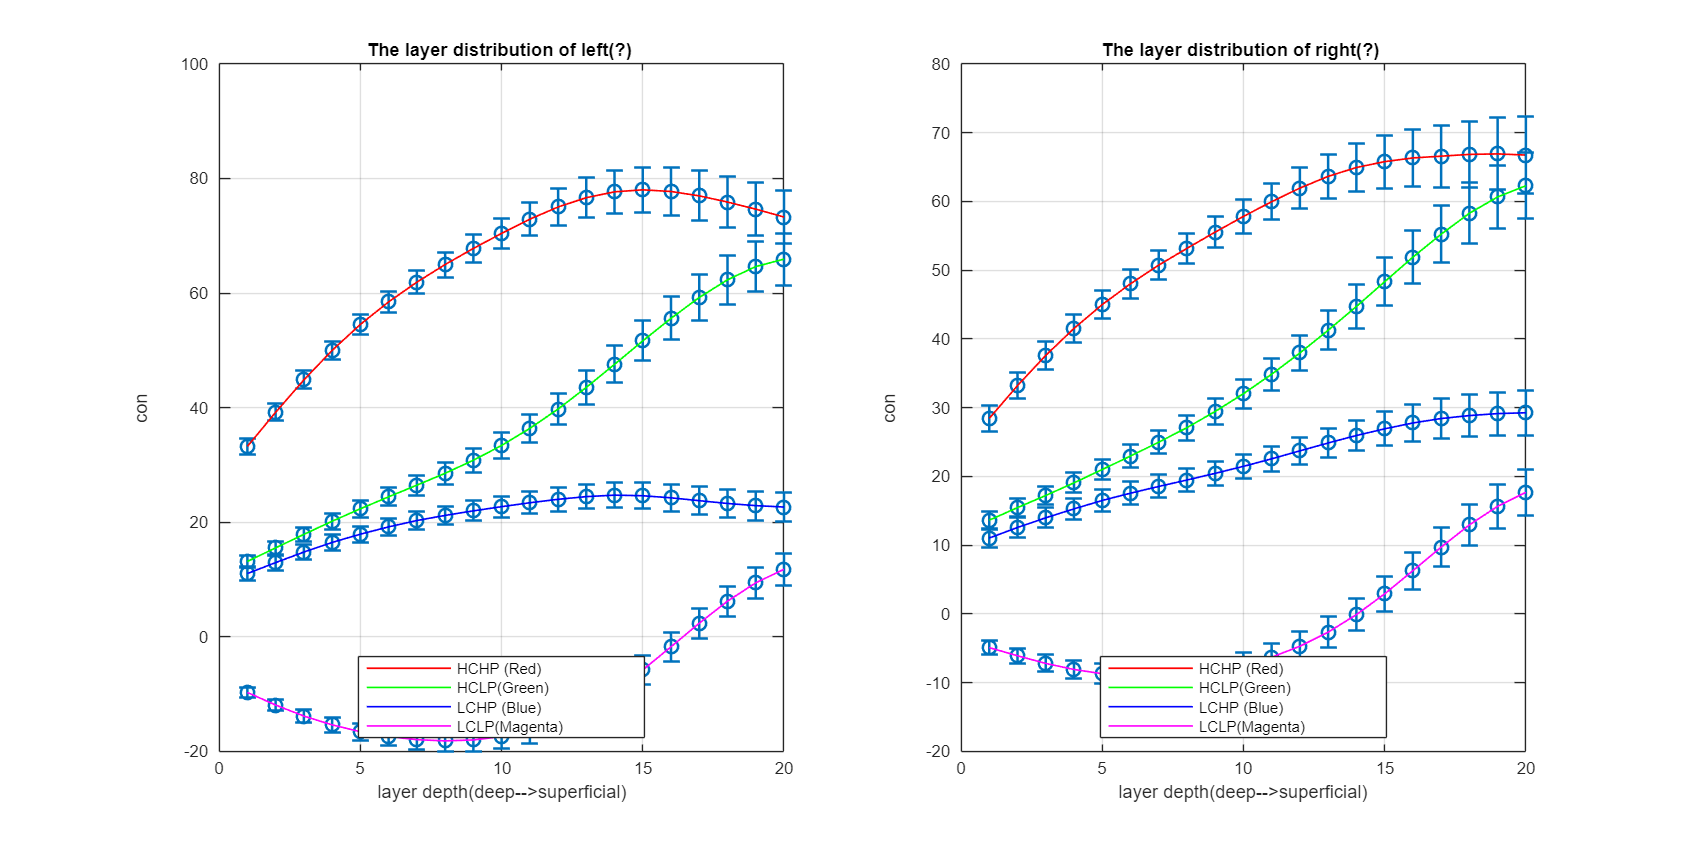

figure('Position',[100, 100, 2400, 1200]);

for roitype=1:2
    alldata={HCHP{roitype,1}, HCLP{roitype,1},...
             LCHP{roitype,1}, LCLP{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) ';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) ';
        
    end
    for dataidx=1:4
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        elseif dataidx==2
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        elseif dataidx==3
            lineHandle3 = plot(1:20, columnMeans, '-b', 'LineWidth', 1);
        elseif dataidx==4
            lineHandle4 = plot(1:20, columnMeans, '-m', 'LineWidth', 1);
            
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2,...
        lineHandle3, lineHandle4], ...
        {'HCHP (Red)', ...
        'HCLP(Green)',...
        'LCHP (Blue)', ...
        'LCLP(Magenta)'}, ...
        'Location', 'south');
    hold off;
end

% save the per condition things into csv
nproc=4;
nsubj=length(allsubjlayer);
nside=2;
allconditions={HCHP, HCLP,...
             LCHP, LCLP};
allconditionsnm={'HCHP', 'HCLP',...
                 'LCHP', 'LCLP'};
myergion=[];
for cond=1:length(allconditions)
    onecond=array2table([allconditions{cond}{1,1};allconditions{cond}{2,1}],'VariableNames',strcat("layer",string(1:20)));
    onecond.process=repmat(allconditionsnm{cond},nsubj*nside,1);
    onecond.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];
    myergion=[myergion;onecond];
end


myergion.subjid=string(repmat(procesubjid',nproc*nside,1));

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\percondition\';

writetable(myergion,[ pathtooutput 'DLPFC_layervalues_percondition.csv'])